Example of a real affine subspace: the set of points in $\mathbb R^3$ on a line $\sum'$ :

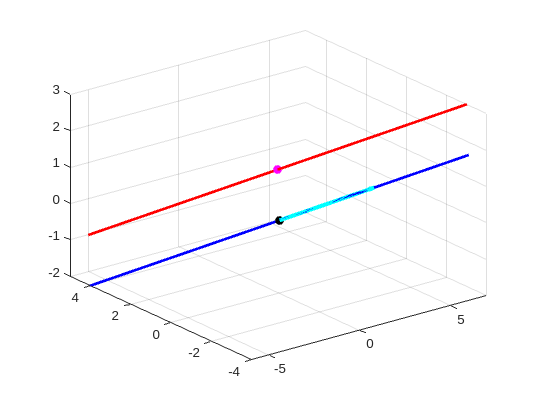

syms a real
u=[3 -2 1]'; V=a*u; %V is the direction space
P0=[1 1 1]'; S=P0+V; %S is the geometric space
fplot3(S(1),S(2),S(3),[-2 2],'Color','r','LineWidth',2)
hold on
fplot3(V(1),V(2),V(3),[-2 2],'Color','b','LineWidth',2)
plot3(0,0,0,'ok','MarkerFaceColor','k')
plot3(P0(1),P0(2),P0(3),'om','MarkerFaceColor','m') %P0
quiver3(0,0,0,u(1),u(2),u(3),1,'Color','c','LineWidth',3) %u vector

Example of a real affine subspace: the set of points in $\mathbb R^3$ on a surface $\sum''$ :

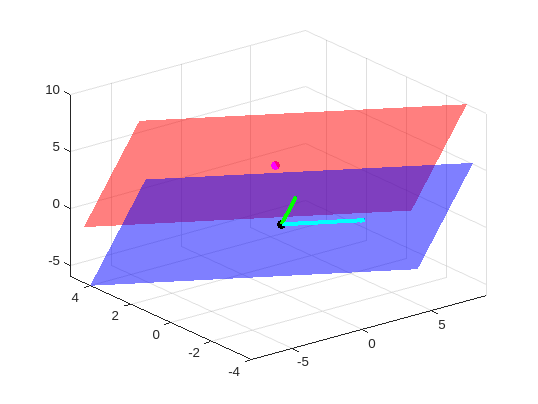

clf
syms a b real;
u=[3 -2 1]'; v=[1 0 2]'; V=[u v]*[a;b]; %V is the direction space
P0=[1 1 4]'; S=P0+V; %S is the geometric space
fmesh(V(1),V(2),V(3),[-2 2],'EdgeColor','none', ...
'FaceColor','b','FaceAlpha',0.5)
hold on
quiver3(0,0,0,u(1),u(2),u(3),1,'Color','c','LineWidth',3)
quiver3(0,0,0,v(1),v(2),v(3),1,'Color','g','LineWidth',3)
fmesh(S(1),S(2),S(3),[-2 2],'EdgeColor','none', ...
'FaceColor','r','FaceAlpha',0.5)
plot3(P0(1),P0(2),P0(3),'om','MarkerFaceColor','m')
plot3(0,0,0,'ok','MarkerFaceColor','k')

clf;

Find the intersection between $\pi$ and $r$

- $\pi=x+z=3$  

- $r: (x,y,z)^T : \;\; (1,1,1)^T + \lambda(0,1,-1)^T$

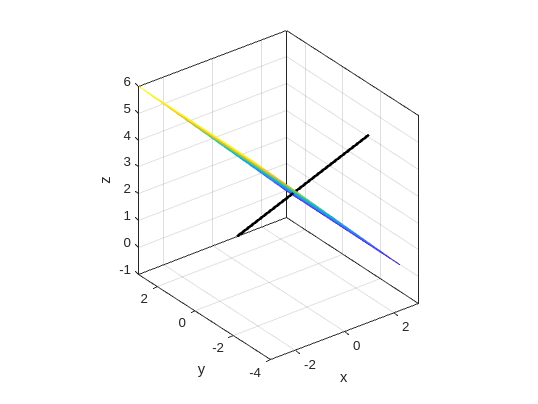

[x,y]=meshgrid(linspace(-3,3,55));
z=3-x; h=mesh(x,y,z); % draw the plane
axis equal; hold on; box on;
syms a real;
r=[1,1,1]' + a*[0,1,-1]';
h=fplot3(r(1),r(2),r(3),[-5 2]); 
set(h,'Color','k','LineWidth',2); xlabel('x'); ylabel('y'); zlabel('z');


%The point of intersection is (1,0,2)
%Let's verify it 
% --------------
% Cartesian to parametric eq algorithm
A=[0 0 -1;-1 1 0; 1 0 1]; b=[-2;1;1];
param=A\b;
sol1=[1,1,1]' + param(1)*[0,1,-1]'; % ∈r
sol1'

ans =      1     0     2


Example Affinely independent points

P=[0 1 -1; 2 3 2]

P =      0     1    -1
     2     3     2


v=P(:,2:end) - P(:,1)

v =      1    -1
     1     0


rank(v) %Linearly independent

ans = 2

%In this case the points are affinely independent